clear
clf
load("Experiment 1\Vin.mat")
load("Experiment 1\Iout_ch2.mat")
load("Experiment 1\Iout_ch1.mat")

%hold on
%grid on
Ve=0

Ve = 0

Ie=-Iout_ch2;
Ib=Iout_ch1;
Ic=Ie-abs(Ib);
%line of best fit
[first, last, mmax, bmax, Nmax]=linefit( Vin,log(Ic), 5e-6);
 Is = exp(bmax)

Is = 6.1754e-15

 Ut = 1/mmax

Ut = 0.0263

 Ic_theory=Is*exp((Vin-Ve)/Ut)

Ic_theory =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


 [first, last, mmax, bmax, Nmax]=linefit(Vin, log(Ib), 5e-6)

first = 0

last = 0

mmax = 0

bmax = 0

Nmax = 0

B =Is/exp(bmax)

B = 6.1754e-15

% Ic=Is*exp((Vin-Ve)/Ut)
Ib_theory=Is/100*exp(Vin/Ut)

Ib_theory = 1.0e-04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


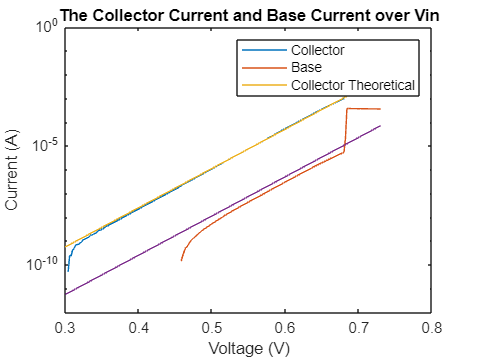

%semilogy(Vin,Ic,Vin,Ib)
semilogy(Vin,Ic,Vin,Ib,Vin,Ic_theory,Vin,Ib_theory)
title("The Collector Current and Base Current over Vin")
legend('Collector','Base','Collector Theoretical')

ylabel("Current (A)")
xlabel("Voltage (V)")